# PCPS acquisition process

Luis Esteve NACC 2025

[luis.esteve@upc.edu](mailto:luis.esteve@upc.edu) Javier Arribas NACC 2018 [jarribas@cttc.es](mailto:jarribas@cttc.es) Simple Parallel Code Phase Search Acquisition algorithm that mimics the GNSS-SDR pcps_acquisition.cc class functionality (only for GPS L1 CA)

H.PARK script, May 2, 2026

The original function is m-function with input parameters and output struct as

where

for this practice, Baseband signal is given in '../../signals/gps_l1_ca_2msps.mat', with the variable name of 'rawSignal'

The sampling frequency of the provided 'rawSignal' is 2MSPS. 

Notice that the front-end used to capture the rawSignal (USRP 1.0) has a very inaccurate LO, thus, it is present a parasitic IF in Doppler shifts. Explore with an acquisition window of -25 kHz to +25 kHz.

## Initial Setting to run the function

clear all
close all
addpath('../../libs');
load('../../signals/gps_l1_ca_2msps.mat');
BB_signal = rawSignal;  % In 'gps_l1_ca_2msps.mat', the variable name is rawSignal

Fs = 2e6;   % Sampling frequency for the BB_signal loaded, 2 MSPS
fs_hz = Fs;

start_doppler_hz = -25e3; % -25 kHz
stop_doppler_hz  =  25e3; %  25 kHz 
doppler_step_hz  =  100;  %  500 Hz (for 1 ms integration, 500 Hz is conventional, in the practice you are varying this value to see how it looks like.

threshold = 5; % Try with 5, it could be [0 10], usually 2 ~ 2.5

SV_ID = 6;     % Let's begin from 1, it will be for loop as 1:32


## Function code, as script file

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% function acqResults = pcps_acquisition(BB_signal, fs_hz, start_doppler_hz, stop_doppler_hz, doppler_step_hz, threshold, SV_ID)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%--- Initialize acqResults ------------------------------------------------
% Carrier frequencies of detected signals
acqResults.carrFreq     = 0;
% C/A code phases of detected signals
acqResults.codePhase    = 0;
% Correlation peak ratios of the detected signals
acqResults.peakMetric   = 0;
acqResults.satellite_detected=0;

% Find number of samples per spreading code
GPS_L1_CA_CODE_FREQ_Hz=1.023e6;
GPS_L1_CA_CODE_LENGTH=1023;
Tsig=1e-3;
samplesPerCode = round(fs_hz*(GPS_L1_CA_CODE_LENGTH/GPS_L1_CA_CODE_FREQ_Hz));

% Compute the number of chips that fits in Tsig and store it in num_chips
num_chips=floor(Tsig/(1/GPS_L1_CA_CODE_FREQ_Hz));
local_replica=digitGPS_L1_CA(num_chips,fs_hz,0,SV_ID,1);
local_replica_FFT = conj(fft(local_replica));
% Find sampling period
ts = 1 / fs_hz;
% Find phase points of the local carrier wave for carrier wippeoff
phasePoints = (0 : (samplesPerCode-1)) * 2 * pi * ts;

% Number of the frequency bins for the given acquisition band
fd_hz=start_doppler_hz:doppler_step_hz:stop_doppler_hz;

numberOfFrqBins = length(fd_hz);
%--- Initialize arrays to speed up the code -------------------------------
% Search results of all frequency bins and code shifts (for one satellite)
results     = zeros(numberOfFrqBins, samplesPerCode);
for frqBinIndex=1:1:numberOfFrqBins
    %--- Generate local sine and cosine -------------------------------
    sigCarr = exp(-1i*fd_hz(frqBinIndex) * phasePoints);
    %--- Remove Doppler from the signal (Doppler wippe-off)------------
    BB_doppler_wipped=BB_signal(1:samplesPerCode).*sigCarr;
    %--- Convert the baseband signal to frequency domain --------------
    BB_doppler_wipped_fft = fft(BB_doppler_wipped);
    %--- Multiplication in the frequency domain (correlation in time
    %domain)
    convCodeIQ = BB_doppler_wipped_fft .* local_replica_FFT;
    %--- Perform inverse DFT and store correlation results ------------
    acqRes = abs(ifft(convCodeIQ)) .^ 2;
    results(frqBinIndex, :) = results(frqBinIndex, :)+acqRes;
end 

## plot the grid

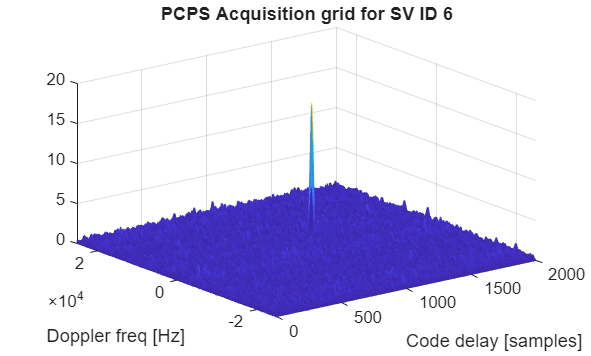

Td=0:1:(samplesPerCode-1);
figure;
mesh(Td,fd_hz,results);
title(['PCPS Acquisition grid for SV ID ', num2str(SV_ID)]);
xlabel('Code delay [samples]');
ylabel('Doppler freq [Hz]');

## Look for correlation peaks in the results ==============================

Find the highest peak and compare it to the second highest peak The second peak is chosen not closer than 1 chip to the highest peak

%--- Find the correlation peak and the carrier frequency --------------
[peakSize,frequencyBinIndex] = max(max(results, [], 2));

%--- Find code phase of the same correlation peak ---------------------
[peakSize,codePhase] = max(max(results));

%--- Find 1 chip wide C/A code phase exclude range around the peak ----
samplesPerCodeChip   = round(fs_hz / GPS_L1_CA_CODE_FREQ_Hz);
excludeRangeIndex1 = codePhase - samplesPerCodeChip;
excludeRangeIndex2 = codePhase + samplesPerCodeChip;

%--- Correct C/A code phase exclude range if the range includes array
%boundaries
if excludeRangeIndex1 < 2
    codePhaseRange = excludeRangeIndex2 : ...
        (samplesPerCode + excludeRangeIndex1);
    
elseif excludeRangeIndex2 >= samplesPerCode
    codePhaseRange = (excludeRangeIndex2 - samplesPerCode) : ...
        excludeRangeIndex1;
else
    codePhaseRange = [1:excludeRangeIndex1, ...
        excludeRangeIndex2 : samplesPerCode];
end

%--- Find the second highest correlation peak in the same freq. bin ---
codePhaseRange(codePhaseRange==0)=[]; %remove any zero index to prevent index out of bounds error on some satellites
secondPeakSize = max(results(frequencyBinIndex, codePhaseRange));

%--- Store result -----------------------------------------------------
acqResults.peakMetric = peakSize/secondPeakSize;

% If the result is above threshold, then there is a signal ...
if (peakSize/secondPeakSize) > threshold
    
    acqResults.satellite_detected=1;
    acqResults.codePhase = codePhase;
    acqResults.carrFreq= fd_hz(frequencyBinIndex);
    
    %--- Indicate PRN number of the detected signal -------------------
    fprintf('Acquired %02d with Doppler %d Hz, Code Phase %d Samples and Test statistics %d \n'...
        , SV_ID, acqResults.carrFreq, acqResults.codePhase, acqResults.peakMetric);
end

Acquired 06 with Doppler 7500 Hz, Code Phase 1272 Samples and Test statistics 1.037006e+01 
